# MAE 158 Drag Calculator

#### Shashwat Sparsh

#### ID: 21697442

### `Profile Drag Coeff`

#### Setup

hp_aircraft = 1;
T = 400;
%P = 1;  % via Table  A.2
R = 1716;
rho = 0.0008754;
speedSound = sqrt(1.4*R*T);
V = [230:1:880];     %765;
M = V/speedSound;    % Mach Number
Sref = 1000;

%% Characteristic Lengths
MACexpW = 0;
MACexpH = 0;
MACexpV = 0;
%Lc = [MACexpW, MACexph, MACexpv, 16.2, 16.8];
Lc = []; %Charactersitic Lengths

%% Ratios
Lf = 119;
Df = 11;
ratios = [0.12, 0.09, 0.09, 0.06, Lf/Df, 5]  % Thickness and Fineness

ratios =     0.1200    0.0900    0.0900    0.0600   10.8182    5.0000


sigma = [0.2, 0.35, 0.8, 1]; % Taper
%% Sexp
Sexpw = 0;  % Defined Later on
Sexp = [Sexpw, 261, 161];
%% Swet
Swet = [0, 0, 0, 117, 0, 455];

#### Component 1 Wing

bW = 93.2;                      % Span
tcW = 0.18;
sweepangleW = 28;               % Sweep Angle
sigmaW = 0.2;                   % Taper Ratio: cT/cR
CRW = 17.8;                     % Root Chord
Coverage_wing = .17;            % Percent Covered
Rfuse = 11/2;

% Getting Swet %
SexpW = (1-Coverage_wing)*Sref;
SwetW = SWET(SexpW);

% Getting Skin Friction Coefficient %
CTW = sigmaW * CRW;
CRexp_wing = CREXP(CRW, CTW, Rfuse, bW);
MACexpW = MAC(CRexp_wing,CTW);
Lc = [Lc, MACexpW];

RNw = ReynoldsNumber(V, MACexpW);
Cf_w = CF(RNw);

% Getting Form Factor %
Kwing = Kairfoil(tcW, M, sweepangleW);

% Calculating f and adding to array %
fwing = F(Kwing, Cf_w, SwetW);

#### Horizontal Tail

SexpH = 261;
tcH = 0.09;
sweepangleH = 31.6;             % Sweep Angle
sigmaH = 0.35;                  % Wing Taper Ratio
CRH = 11.1;                     % Root Chord

% Getting Swet %
SwetH = SWET(SexpH);

% Getting Skin Friction Coefficient %
CTH = sigmaH * CRH;
MACexpH = MAC(CRH,CTH);
Lc = [Lc, MACexpH];

RNh = ReynoldsNumber(V, MACexpH);
Cf_h = CF(RNh);

% Getting Form Factor %
Khoriztail = Kairfoil(tcH, M, sweepangleH);

% Calculating f and adding to array %
fhoriztail = F(Khoriztail, Cf_h, SwetH);

#### Vertical Tail

SexpV = 161;
tcV = 0.09;
sweepangleV = 43.5;             % Sweep Angle 
sigmaV = 0.8;                   % Wing Taper Ratio
CRV = 15.5;                     % Root Chord

% Getting Swet %
SwetV = SWET(SexpV);

% Getting Skin Friction Coefficient %
CTV = sigmaV * CRV;
MACexpV = MAC(CRV,CTV);
Lc = [Lc, MACexpV];

RNv = ReynoldsNumber(V, MACexpV);
Cf_v = CF(RNv);

% Getting Form Factor %
Kverttail = Kairfoil(tcV, M, sweepangleV);

% Calculating f and adding to array %
fverttail = F(Kverttail, Cf_v, SwetV);

#### Pylons

SwetP = 117;                    % Wetted Area
tcP = 0.06;
sweepangleP = 0;                % Sweep Angle
sigmaP = 1;                     % Taper Ratio: cT/cR
chordP = 16.2;                  % Chord

% Getting Skin Friction Coefficient %
Lc = [Lc, chordP];
RNp = ReynoldsNumber(V, chordP);
Cf_p = CF(RNp);

% Getting Form Factor %
Kpylon = Kairfoil(tcP, M, sweepangleP);

% Calculating f and adding to array %
fpylon = F(Kpylon, Cf_p, SwetP);

#### Component 2: Fuselage

Lf = 105;
Df = 11;

% Calculating Swet %
SwetF = 0.8 * pi * Df * Lf;

% Getting Skin Friction Coefficient %
RNf = ReynoldsNumber(V, Lf);
Lc = [Lc, Lf];
Cf_f = CF(RNf);

% Getting Form Factor %
ratioF = Lf/Df;
Kfuse = KFR(ratioF);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
ffuselage = F(Kfuse, Cf_f, SwetF);

#### Nacelles

% Swet %
SwetN = 455;

% Getting Skin Friction Coefficient %
Ln = 16.8;
Lc = [Lc, Ln];
RNn = ReynoldsNumber(V, 16.8);
Cf_n = CF(RNn);

% Getting Form Factor %
ratioN = 5;
Knacelle = KFR(ratioN);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
fnacelle = F(Knacelle, Cf_n, SwetN);

### Profile Drag Coeff Calculation

ftotal = fwing + fhoriztail + fverttail + fpylon + ffuselage + fnacelle;
CDP_total = 1.10 * ftotal./Sref;

### `Induced Drag Coeff`

% Getting CL %
W = 98000;              % Aircraft Weight
q = 0.5 * rho * (V.^2);  % Dynamic Pressure
CL = W ./ (q * Sref);     % Coeff of Lift
% Getting Aspect Ratio %
ARw = (bW^2)/Sref;
% Getting CDi %
efactor = oswaldEff(ARw, CDP_total);        % Oswald Efficiency Factor
e = 1;                                      % Ignore
CDi = (CL.^2) ./ ((pi * ARw) .* efactor);   % Coeff of Induced Drag

## Total Drag & Lift/Drag Ratio

ProfileDrag = CDP_total .* q .* Sref;
InducedDrag = CDi .* q .* Sref;
CDtotal = CDP_total + CDi;
TotalDrag = CDtotal .* q .* Sref;
L = W;
LiftToDrag = L ./ TotalDrag;
[LiftToDragMax, index] = max(LiftToDrag)

LiftToDragMax = 16.9434

index = 370

max(LiftToDrag)

ans = 16.9434

Voptimum = V(index)

Voptimum = 599

## V  = 765 ft/s Information

This section is used to verify the software to the hand calculations

indexV765 = find(V==765);
%{
M765 = M(indexV765);
%   Profile Calculation__
%   Wing Data
ChordVals = [CRW, CTW, CRexp_wing, MACexpW];
RNw(indexV765);
Cf_w(indexV765);
%   Horizontal Tail Data
ChordVals = [CRH, CTH, MACexpH];
RNh(indexV765);
%   Vertical Tail Data
ChordVals = [CRV, CTV, MACexpV];
RNv(indexV765);
%   Pylons
RNp(indexV765);
%   Nacelles
RNn(indexV765);
%   Fuselage
RNf(indexV765);
SwetF;
%   Profile Total
CDP_total(indexV765);
ProfileDrag(indexV765);
%   Induced Calculation__
%   CL
q(indexV765);
CL(indexV765);
ARw;
efactor(indexV765);
CDi(indexV765);
%   Total Calculations__
CDtotal(indexV765);
TotalDrag(indexV765);
LiftToDrag(indexV765);
%}
%   Table Info
ComponentName = ["#", "Component", "Leff", "Re", "Cf", "K", "Swet", "CDP"];
WingValues = ["Wing", MACexpW, RNw(indexV765), Cf_w(indexV765), Kwing(indexV765), SwetW, fwing(indexV765) + "/1000"];
FuselageValues = ["Fuselage", Lf, RNf(indexV765), Cf_f(indexV765), Kfuse, SwetF, ffuselage(indexV765) + "/1000"];
HTailValues = ["H. Tail", MACexpH, RNh(indexV765), Cf_h(indexV765), Khoriztail(indexV765), SwetH, fhoriztail(indexV765) + "/1000"];
VTailValues = ["V. Tail", MACexpV, RNv(indexV765), Cf_v(indexV765), Kverttail(indexV765), SwetV, fverttail(indexV765) + "/1000"];
PylonValues = ["Pylon", chordP, RNp(indexV765), Cf_p(indexV765), Kpylon(indexV765), SwetP, fpylon(indexV765) + "/1000"];
NacelleValues = ["Nacelles", Ln, RNn(indexV765), Cf_n(indexV765), Knacelle, SwetN, fnacelle(indexV765) + "/1000"];
testTable = [WingValues; FuselageValues; HTailValues; VTailValues; PylonValues; NacelleValues];
FinalTable = array2table(testTable);
FinalTable.Properties.VariableNames(1:7) = {'Component','Leff','Re','Cf','K','Swet','CDP'};
writetable(FinalTable, 'FinalTable.csv');       %   Generate CSV Table

## `Plots`

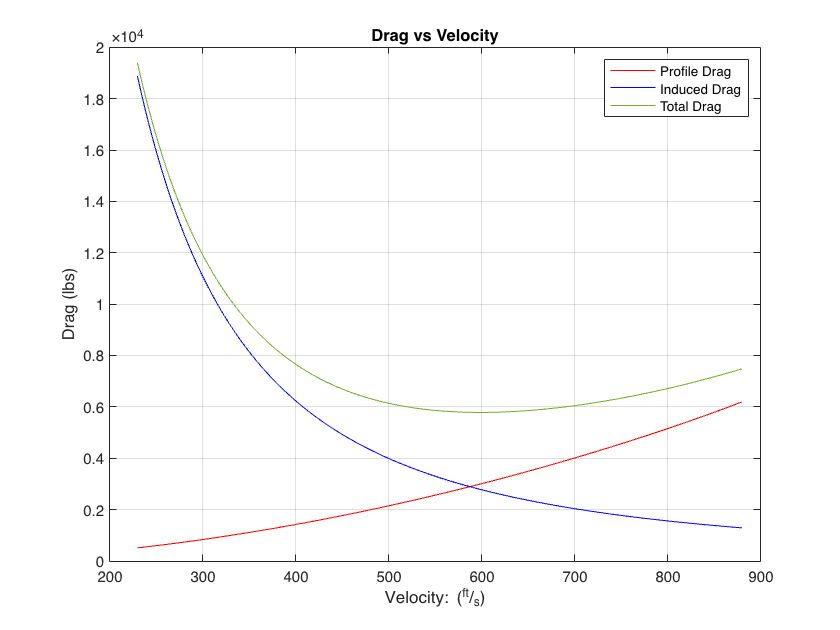

plot(V, ProfileDrag, 'r', V, InducedDrag, 'b')
hold on;
plot(V, TotalDrag, Color=[0.4660 0.6740 0.1880])
grid on
title("Drag vs Velocity")
ylabel("Drag (lbs)")
xlabel("Velocity: (^{ft}/_{s})")
legend("Profile Drag", "Induced Drag", "Total Drag")
hold off

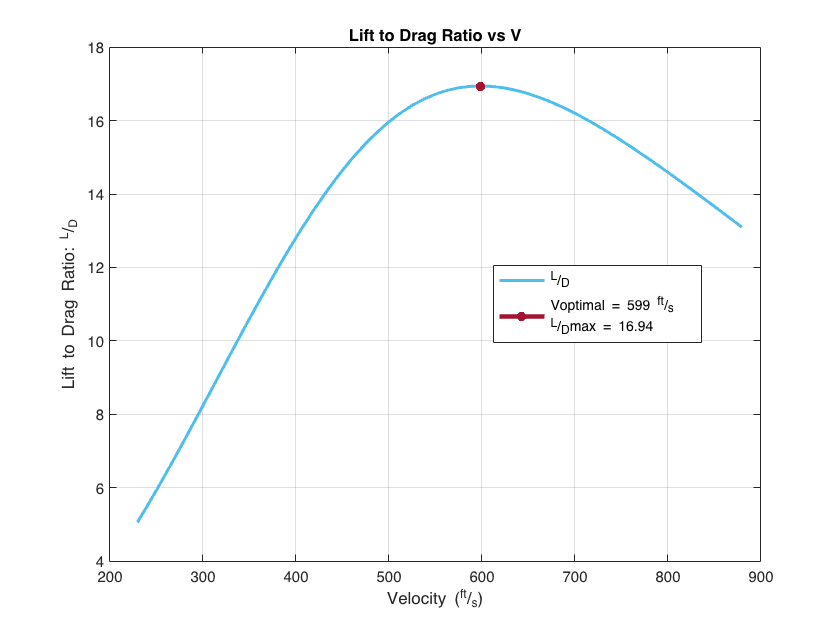

plot(V,LiftToDrag, Color=[0.3010 0.7450 0.9330], LineWidth=2)
hold on
%plot(Voptimum, LiftToDragMax, 'Color', 'r', 'Marker','o', 'LineWidth',1)
plot(Voptimum, LiftToDragMax, Color=[0.6350 0.0780 0.1840], Marker="*", LineWidth=3);
grid on
title("Lift to Drag Ratio vs V")
ylabel("Lift to Drag Ratio: ^{L}/_{D}")
xlabel("Velocity (^{ft}/_{s})")
legend("^{L}/_{D}","Voptimal = 599 ^{ft}/_{s}" + newline + "^{L}/_{D}max = 16.94",Location="best")
hold off;

## `Functions`

#### Reynolds Number Function

function RN = ReynoldsNumber(Velocity, characteristicLength)
    mu = 3.025E-7;
    rho = 0.0008754;
    V = Velocity;
    Lc = characteristicLength;
    RN = (rho * V * Lc)/mu;
end

#### Swet Function

function Swet = SWET(Sexp)
    Swet = 2 * 1.02 * Sexp;
end

#### MAC Function

function cbar = MAC(cR, cT)
    cbar= (2/3) * (cR + cT - ((cR*cT)/(cR+cT)));
end

#### CR Exposed Function

function crexp = CREXP(cR, cT, y, b)
    crexp = cR - ((cR- cT)*(2*(y/b)));
end

#### Skin Friction Coefficient

function Cf = CF(RN)
    Cf = 0.455 ./ ((log10(RN)).^2.58);
end

#### Form Factor for Airfoils

function K = Kairfoil(tc, Mo, sweepAngle)
    numTerm = (2-Mo.^2) * cosd(sweepAngle);
    denTerm = sqrt(1-((Mo.^2)*cosd(sweepAngle)));
    Z = numTerm./denTerm;
    K = 1 + (Z .* tc) + (100*tc^4);
end

#### Form Factor via Fineness Ratio

function K = KFR(LbyD)
    K = 1.991*LbyD^-1.024+0.9084;
    % General model Power2:
    % Coefficients (with 95% confidence bounds):
    %    a =       1.991  (1.882, 2.101)
    %    b =      -1.024  (-1.091, -0.9582)
    %    c =      0.9084  (0.8888, 0.9279)
end

#### F Function

function f = F(K, Cf, Swet)
    f = K .* Cf * Swet;
end

#### Oswald Efficiency Function

function e = oswaldEff(ARW, CDP)
    e = [];
    for N = 1:length(CDP)
        CDProunded = round(CDP(N),2);   % Skips Interpolation
        switch CDProunded
            case .01
                e = [e, .000114*ARW^2 - .01085*ARW + .9659];                        % e vs ARw, CDP = .01
            case .015
                e = [e, (2.5e-05)*ARW^3 - .0002244*ARW^2 - .01422*ARW + .9649];     % e vs ARw, CDP = .015
            case  .02
                e = [e, .000364*ARW^2 - .02149*ARW + .9641];                        % e vs ARw, CDP = .02
            case .025
                e = [e, (-6.849e-06)*ARW^3 + .0006443*ARW^2 - .0269*ARW + .9614];   % e vs ARw, CDP = .025
        end
    end
end

%% Digitized Curved Results for Oswald Efficiency Factor %%
%{
    CDP = .01
    f(x) = p1*x^2 + p2*x + p3
    Coefficients (with 95% confidence bounds):
        p1 =    0.000114  (0.000103, 0.0001251)       
        p2 =    -0.01085  (-0.01099, -0.01071)       
        p3 =      0.9659  (0.9655, 0.9663)
%}
%{
    CDP = .015
    f(x) = p1*x^3 + p2*x^2 + p3*x + p4
    Coefficients (with 95% confidence bounds):       
        p1 =     2.5e-05  (1.971e-05, 3.03e-05)       
        p2 =  -0.0002244  (-0.0003207, -0.0001281)       
        p3 =    -0.01422  (-0.01471, -0.01373)       
        p4 =      0.9649  (0.9642, 0.9655)
%}
%{
    CDP = .02
    f(x) = p1*x^2 + p2*x + p3
    Coefficients (with 95% confidence bounds):       
        p1 =    0.000364  (0.0003456, 0.0003824)       
        p2 =    -0.02149  (-0.02171, -0.02126)       
        p3 =      0.9641  (0.9635, 0.9647)
%}
%{
    CDP = .025
    f(x) = p1*x^3 + p2*x^2 + p3*x + p4
    Coefficients (with 95% confidence bounds):       
        p1 =  -6.849e-06  (-1.049e-05, -3.207e-06)       
        p2 =   0.0006443  (0.0005786, 0.0007101)       
        p3 =     -0.0269  (-0.02723, -0.02656)       
        p4 =      0.9614  (0.961, 0.9619)
%}
